## 1 system

syms x1 x2
syms p11 p12 p21 p22

P = [p11 p12;
     p21 p22]

$$P = \left(\begin{array}{cc} p_{11} & p_{12}\\ p_{21} & p_{22} \end{array}\right)$$

x = [x1; x2]

$$x = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$

x_dot = [-x1+x1*x2;
         -2*x2]

$$x\_dot = \left(\begin{array}{c} x_{1}\,x_{2}-x_{1}\\ -2\,x_{2} \end{array}\right)$$

V = x.'*P*x

$$V = x_{1}\,\left(p_{11}\,x_{1}+p_{21}\,x_{2}\right)+x_{2}\,\left(p_{12}\,x_{1}+p_{22}\,x_{2}\right)$$

V_dot = (x_dot.'*P*x+x.'*P*x_dot)/2

$$V\_dot = -\frac{\left(x_{1}-x_{1}\,x_{2}\right)\,\left(p_{11}\,x_{1}+p_{21}\,x_{2}\right)}{2}-\frac{x_{1}\,\left(2\,p_{21}\,x_{2}+p_{11}\,\left(x_{1}-x_{1}\,x_{2}\right)\right)}{2}-\frac{x_{2}\,\left(2\,p_{22}\,x_{2}+p_{12}\,\left(x_{1}-x_{1}\,x_{2}\right)\right)}{2}-x_{2}\,\left(p_{12}\,x_{1}+p_{22}\,x_{2}\right)$$

collect(V_dot, x)

$$ans = p_{11}\,{x_{1}}^{2}\,x_{2}+\left(-p_{11}\right)\,{x_{1}}^{2}+\left(\frac{p_{12}}{2}+\frac{p_{21}}{2}\right)\,x_{1}\,{x_{2}}^{2}+\left(-\frac{3\,p_{12}}{2}-\frac{3\,p_{21}}{2}\right)\,x_{1}\,x_{2}+\left(-2\,p_{22}\right)\,{x_{2}}^{2}$$

Для того, чтобы производная функции Ляпунова была отрицательно определена, выберем p11=0, p12=-p21, p22 != 0.

Если матрица P будет положительно определена, то и функция Ляпунова будет положительно определена, а следовательно начало координат будет асимптотически устойчиво.

collect(subs(V, [p11, p12, p21, p22], [0, 10, -10, 100]))

$$ans = 100\,{x_{2}}^{2}$$

Функция V=x^T*P*x при выбранных параметрах матрицы P является положительно определенной.

eig([0 10;
    -10 100])

ans =     1.0102
   98.9898


Так как все собственные числа положительны, то матрица P положительно определена. Значит начало координат асимптотически устойчиво.

Также начало координат глобально устойчиво, так как выбранная функция Ляпунова V(x)=x^T*P*x является радиально неограниченной.

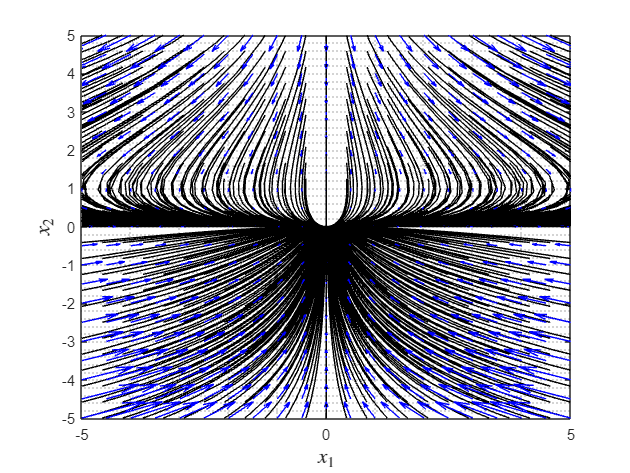

% phase portrait
xlim = [-5; 5];
ylim = [-5; 5];
n_traj = [25; 25];
tspan=[0,5];

[x_init,y_init] = meshgrid(linspace(xlim(1), xlim(2), n_traj(1)), linspace(ylim(1), ylim(2), n_traj(2)));
icond=cell(1,numel(x_init));
for n=1:numel(x_init)
    icond{n}=[x_init(n),y_init(n)];
end

warning('off')
figure;
PhasePlane(@system1,tspan,icond,'scale',2,'Xlim',xlim,'Ylim',ylim);

## 2 system

x_dot = [-x2-x1*(1-x1^2-x2^2);
         x1-x2*(1-x1^2-x2^2)]

$$x\_dot = \left(\begin{array}{c} x_{1}\,\left({x_{1}}^{2}+{x_{2}}^{2}-1\right)-x_{2}\\ x_{1}+x_{2}\,\left({x_{1}}^{2}+{x_{2}}^{2}-1\right) \end{array}\right)$$

V = x1^2 + x2^2

$$V = {x_{1}}^{2}+{x_{2}}^{2}$$

V_dot = simplify(2*x1*x_dot(1) + 2*x2*x_dot(2))

$$V\_dot = 2\,{x_{1}}^{4}+4\,{x_{1}}^{2}\,{x_{2}}^{2}-2\,{x_{1}}^{2}+2\,{x_{2}}^{4}-2\,{x_{2}}^{2}$$

Преобразовав выражение, получим:

V_dot = 1/2*(x1^2+x2^2)^2-2*x1^2-2*x2^2

$$V\_dot = \frac{{\left({x_{1}}^{2}+{x_{2}}^{2}\right)}^{2}}{2}-2\,{x_{1}}^{2}-2\,{x_{2}}^{2}$$

V_dot = 2*(x1^2+x2^2)*(x1^2+x2^2-1)

$$V\_dot = \left(2\,{x_{1}}^{2}+2\,{x_{2}}^{2}\right)\,\left({x_{1}}^{2}+{x_{2}}^{2}-1\right)$$

Итого, в открытой области D = {(x1, x2): x1^2+x2^2 < 1} производная функции Ляпунова будет отрицательно определенной, а следовательно, точка равновесия начала координат данной системы в этой области будет асимптотически устойчива.

Для доказательства глобальной устойчивости данная функция V(x) не подходит, необходимо либо искать подходящий кандидат, либо использовать теорему, которая устанавливает условие нейстойчивости точки равновесия (н-р теорема Четаева), либо проанализировать фазовый портрет системы.

S = solve(system2(x) == 0);
ep = [S.x1 S.x2]

$$ep = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

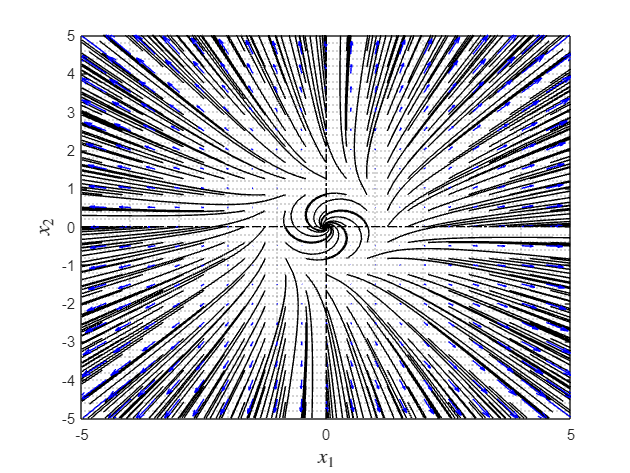

% phase portrait
xlim = [-5; 5];
ylim = [-5; 5];
n_traj = [25; 25];
tspan=[0,5];

[x_init,y_init] = meshgrid(linspace(xlim(1), xlim(2), n_traj(1)), linspace(ylim(1), ylim(2), n_traj(2)));
icond=cell(1,numel(x_init));
for n=1:numel(x_init)
    icond{n}=[x_init(n),y_init(n)];
end

warning('off')
figure;
PhasePlane(@system2,tspan,icond,'scale',2,'Xlim',xlim,'Ylim',ylim);

Судя по фазовому потрету, траектории начинающиеся в области Q = {(x1, x2): x1^2 + x2^2 >=1} расходятся в бесконечность. Следовательно начало коориднат данной системы не является глобально устойчивым

Проанализируем систему в области Q:

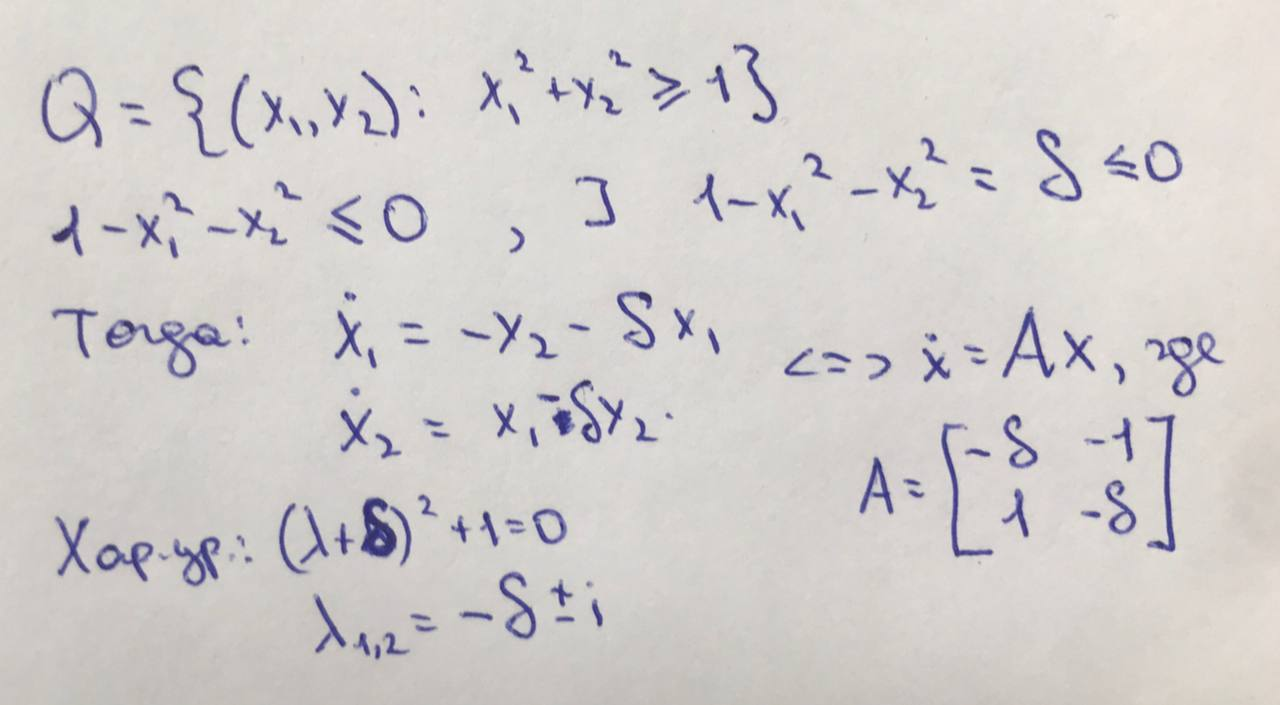

Итак, в области Q можем представить поведение исходной нелинейной системы в виде описанной выше линейной системы с изменяющимся параметром delta.

Значение delta не будет >0, так как собственные числа не имеют отрицательной вещественной части, а следовательно норма вектора состояния будет увеличиваться, в то время как delta будет уменьшаться.

Значит начало координат не является глобально устойчивым.

## 3 system

x_dot = [x2*(1-x1^2)-2*x1;
         -(x1+x2)*(1-x1^2)]

$$x\_dot = \left(\begin{array}{c} -2\,x_{1}-x_{2}\,\left({x_{1}}^{2}-1\right)\\ \left({x_{1}}^{2}-1\right)\,\left(x_{1}+x_{2}\right) \end{array}\right)$$

S = solve(system3(x) == 0);
ep = [S.x1 S.x2]

$$ep = \left(\begin{array}{cc} 0 & 0\\ -\sqrt{3} & \sqrt{3}\\ \sqrt{3} & -\sqrt{3} \end{array}\right)$$

Так как у системы существует несколько точек равновесия, то вопрос о глобальной асимптотической устойчивости начала координат не может стоять. Так как если существует другая точка равновесия, помимо начала координат, то любая траектория, начинающаяся в этой точке, не покидает её при всех моментах времени t>=0 и, следовательно, не стремится к началу координат.

V = x1^2+x2^2

$$V = {x_{1}}^{2}+{x_{2}}^{2}$$

V_dot = simplify(2*x1*x_dot(1) + 2*x2*x_dot(2))

$$V\_dot = 2\,{x_{1}}^{2}\,{x_{2}}^{2}-4\,{x_{1}}^{2}-2\,{x_{2}}^{2}$$

Перепишем выражение в виде:

V_dot = -2*x1^2-2*x1^2*(1-x2^2)

$$V\_dot = 2\,{x_{1}}^{2}\,\left({x_{2}}^{2}-1\right)-2\,{x_{1}}^{2}$$

Итого, в области D = {(x1, x2): x2^2 < 1} производная функции Ляпунова будет отрицательно определенной, а следовательно, точка равновесия начала координат данной системы в этой области будет асимптотически устойчива.

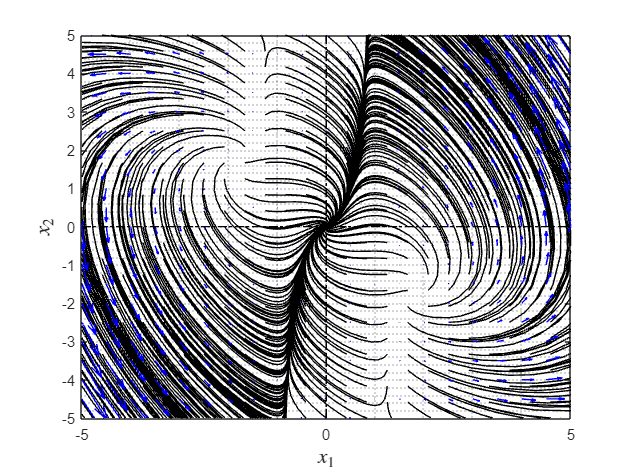

% phase portrait
xlim = [-5; 5];
ylim = [-5; 5];
n_traj = [25; 25];
tspan=[0,5];

[x_init,y_init] = meshgrid(linspace(xlim(1), xlim(2), n_traj(1)), linspace(ylim(1), ylim(2), n_traj(2)));
icond=cell(1,numel(x_init));
for n=1:numel(x_init)
    icond{n}=[x_init(n),y_init(n)];
end

warning('off')
figure;
PhasePlane(@system3,tspan,icond,'scale',2,'Xlim',xlim,'Ylim',ylim);

## 4 system

x_dot = [-3*x1-x2;
         2*x1-x2^3]

$$x\_dot = \left(\begin{array}{c} -3\,x_{1}-x_{2}\\ 2\,x_{1}-{x_{2}}^{3} \end{array}\right)$$

S = solve(system4(x) == 0);
ep = [S.x1 S.x2]

$$ep = \left(\begin{array}{cc} 0 & 0\\ \frac{\sqrt{6}\,\mathrm{i}}{9} & -\frac{\sqrt{6}\,\mathrm{i}}{3}\\ -\frac{\sqrt{6}\,\mathrm{i}}{9} & \frac{\sqrt{6}\,\mathrm{i}}{3} \end{array}\right)$$

V = x1^2+1/2*x2^2

$$V = {x_{1}}^{2}+\frac{{x_{2}}^{2}}{2}$$

V_dot = simplify(2*x1*x_dot(1) + x2*x_dot(2))

$$V\_dot = -6\,{x_{1}}^{2}-{x_{2}}^{4}$$

Так как производная функции Ляпунова отрицательно определена на всем R, а сама функция Ляпунова положительно определена на всем R, и выполняется условие радиальной неограниченности, то начало координат глобально устойчиво.

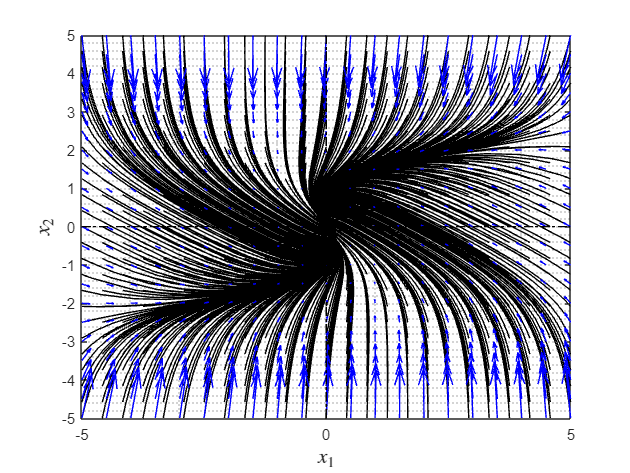

% phase portrait
xlim = [-5; 5];
ylim = [-5; 5];
n_traj = [25; 25];
tspan=[0,5];

[x_init,y_init] = meshgrid(linspace(xlim(1), xlim(2), n_traj(1)), linspace(ylim(1), ylim(2), n_traj(2)));
icond=cell(1,numel(x_init));
for n=1:numel(x_init)
    icond{n}=[x_init(n),y_init(n)];
end

warning('off')
figure;
PhasePlane(@system4,tspan,icond,'scale',2,'Xlim',xlim,'Ylim',ylim);

## Задание 2